%% BIOE464 Monte Carlo Project
clear all
clc

%% Initialize Constant Parameters
N = 500;                %number of particles
T = [0.9 2.0];          %temperature values in reduced units
beta = 1./T;       %beta in reduced units
density = 0.1:0.1:0.8;    %different densities
Nstep = 2000;            %simulation steps

%% Monte Carlo Test with One Density, One Temp
rho = density(5);    %density of 0.5
b = beta(1);         %with T = 0.9
L = (N/rho)^(1/3);   %determine length of side of cubic lattice (L = 10 here)

%% Create initial particle values
initial_coords = create_coords(N,L);  %create coordinates of particles
initial_energies = compute_whole_lattice_E(initial_coords,L);   %compute energies of particles
proposed_energy_matrix=zeros(1,N); % matrix to save energy of each particle in it
tic
for trial = 1:Nstep
    if trial == 1
        % Assign all initial particle values to current variables of all particles
        all_current_coords = initial_coords(:,:);
        all_current_energies = initial_energies(:,:);
    end

    % Assign initial particle position and energy of single particle
    particle = randi([1 N]);
    particle_position = all_current_coords(:,particle);
    particle_energy = all_current_energies;

    % Simulate proposed movement of single particle
    proposed_coordinate_lattice = displace_particle(particle,all_current_coords,L);
    proposed_movement = proposed_coordinate_lattice(:,particle);
    
    % Find new energy of proposed movement
    proposed_energy = compute_E(particle,proposed_coordinate_lattice,L);
    proposed_energy_matrix(1,particle)=proposed_energy(1,particle);
    
    % Accept/reject based on Boltzmann
    [updated_coord updated_energy] = accept_reject(particle_position, proposed_movement,particle_energy, proposed_energy_matrix(particle), b);    %accept/reject based on Boltzmann factor

    % Update coords and energies for next particle
    all_current_coords(:,particle) = updated_coord; %updates matrix with all coordinates
    all_current_energies = updated_energy;
    
    energies(trial) = all_current_energies; %sums updated energies of each particle
end
toc

Elapsed time is 0.693442 seconds.


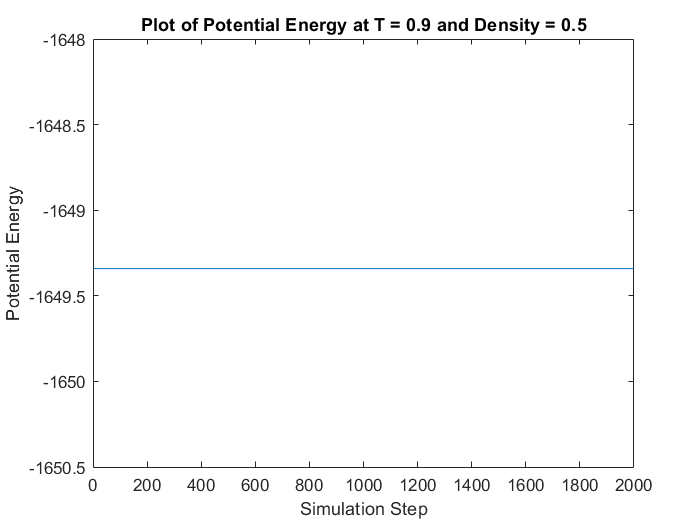

%% Plot in normal scale
figure(1)
energies = [sum(initial_energies) energies];

%{
fileID=fopen('energies.txt','w');
fprintf(fileID,'%6s %12s\n','trial','energies');
fprintf(fileID,'%6.2f %12.8f\n',[nstep;energies]);
fclose(fileID);
%}

plot([0 1:Nstep],energies)
xlabel('Simulation Step')
ylabel('Potential Energy')
title('Plot of Potential Energy at T = 0.9 and Density = 0.5')


%% Plot in logarithmic scale with values > 0 only
% figure(1)
% semilogy(1:Nstep,energies)
% xlabel('Simulation Step')
% ylabel('Potential Energy')
% title('Plot of Potential Energy at T = 0.9 and Density = 0.5')

%% Plot in logarithmic scale and including values < 0
% figure(1)
% energies = sign(energies).*log10(abs(energies));
% plot(1:Nstep,energies)
% y1 = get(gca,'ytick');
% set(gca,'yticklabel',sign(y1).*10.^abs(y1));
% xlabel('Simulation Step')
% ylabel('Potential Energy')
% title('Plot of Potential Energy at T = 0.9 and Density = 0.5')